# 2.1.02. Создание интерактивных лекций в Live Editor

**Практическое занятие**

## Введение

Вы открыли так называемый "живой скрипт" (**Live Script**). С их помощью в редакторе **Live Editor** вы можете создавать увлекательные интерактивные лекции на любые темы (не связанные с MATLAB) и по любым предметам. Live Editor позволяет:

- Создавать интерактивные красивые документы с форматированием, картинками, формулами и ссылками

- Вставлять и выполнять в скрипте MATLAB-код с сохранением результатов

- Вести отладку и выполнять скрипт построчно

- Экспортировать скрипт в *PDF*, *HTML* или *LaTeX* форматы

## Задание

Далее приведена простая лекция по физике на тему **"Свободное падение"**. Ваша задача:

- Целиком отформатировать этот скрипт: выделить загловки (*Title*, *Heading*) и важные моменты (*Bold*, *Italic*, *Underline, Numbered List*)

- В начале скрипта вставить оглавление (*Insert -> Table of Contents*)

- Разбить скрипт на секции по смыслу (*Insert -> Section Break*)

- Встречающийся в скрипте MATLAB-код оформить в секции кода (*Insert -> Code*)

- Где указано, вставить картинки и анимацию (*Insert -> Image*)

- Встречающиеся формулы набрать в редакторе или вставить в LaTeX (*Insert -> Equation*)

- Встречающиеся ссылки спрятать за текстом (*Insert -> Hyperlink*)

- Объявление переменных обернуть в интерактивные элементы (*Insert -> Control*)

## Лекция по физике "Свободное падение"

### Введение

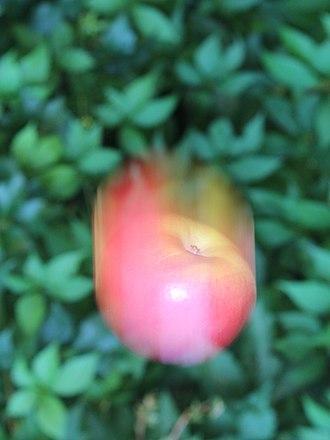

**Свобо́дное падéние** — равнопеременное движение под действием силы тяжести, когда другие силы, действующие на тело, отсутствуют или пренебрежимо малы. На поверхности Земли (на уровне моря) ускорение свободного падения меняется от *9,832 м/с²* на полюсах, до *9,78 м/с²* на экваторе.

В частности, парашютист в течение нескольких первых секунд прыжка находится практически в свободном падении.

Подробнее на [Википедии](https://ru.wikipedia.org/wiki/Свободное_падение)

### Демонстрация явления

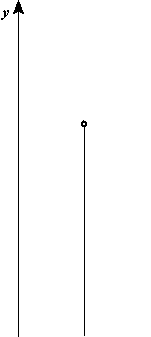

Свободное падение. Вектор силы тяжести направлен вертикально вниз. При демонстрации явления свободного падения откачивают воздух из длинной трубки, в которую помещают несколько предметов разной массы. Если перевернуть трубку, то тела, независимо от их массы, упадут на дно трубки одновременно.

### Уравнение движения

Дифференциальное уравнение движения тела в проекции на ось *y* имеет вид:


$${\displaystyle m{\ddot {y}}\;=\;-\,mg\,}$$


Интегрируя данное дифференциальное уравнение при заданных начальных условиях $v=v_0$, находим зависимость скорости падения $v$ от времени $t$


$$v=v_0 +g\cdot t$$


В частном случае, когда начальная скорость равна нулю (то есть тело начинает падение, не испытав толчка вверх или вниз), из формулы видно, что текущая скорость тела пропорциональна *времени*, прошедшему с момента начала свободного падения.

Подчеркнём, что скорость падения не зависит от массы тела *m.*

### Моделирование движения

Промоделируем падение тела на языке MATLAB.

Задаем ускорение свободного падения

g = 9.8;

Задаем начальную скорость

v0 = 42;

Зададим вектор времени

t = 0:1:10;

По приведенной формуле рассчитаем скорость падения

v = v0 + g*t;

### Визуализация движения

Построим график скорости `v` от времени `t`

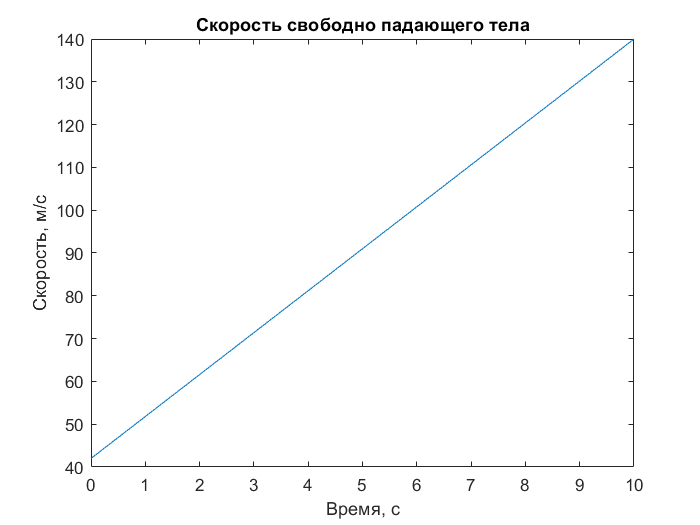

plot(t, v)
title('Скорость свободно падающего тела')
xlabel('Время, с')
ylabel('Скорость, м/с')

Выполните эту секцию кода кнопкой *Run Section (Ctrl+Enter).* Или можете выполнить весь скрипт кнопкой *Run (F5)*

С помощью слайдера изменяйте начальное значение скорости `v0` от **0** до **100** м/с и наблюдайте, как график скорости смещается вверх, характер падения при этом не меняется.